We consider a clamped-pinned beam. 

Nayfeh [1] and Li [2] inverstigated the forced response of such a system under external harmonic response. Specifically, modal expansion (with linear modes) is used to transfer PDEs to a set of ODEs


$$\ddot{u}_n+\omega_n^2u_n=-2c_n\dot{u}_n+\nu\sum_{m,p,q}\alpha_{nmpq}u_mu_pu_q+\epsilon\left(f_n\cos\lambda t\right), n=1,\cdots,$$


This set of ODEs has to be adjusted for the case where the harmonic excitation  $p_a(t)$ occurs in an axial direction and direct transverse excitation is applied as $p_t(x,t)$, where $x$ are dimensionless coordinates along the beam . Then the equations of the modal coordinates in transverse direction read

 
$$\omega_j^2 u_j + \ddot{u}_j +  2c_j\dot{u}_j= \nu\sum_{i,k,s} \alpha_{jiks} u_i u_k u_s   + \epsilon \bigg(f_j(t) + \sum_i p_a(t) u_i a_{ji}\bigg)$$


where the coefficients $a_{ji}$ are defined in terms of the spatial eigenmodes as


$$a_{ji} := \int_0^l  \psi_j \ \psi''_i dx$$


and


$$f_j = \int_0^l  \psi_j p(x,t) dx$$


Here no mode is ecited externall so $f_j = 0$ for all $j$ and $p_a(t) = \mu \cos(\Omega t)$. The system is forced around the principal resonance of the first mode so $\Omega \approx 2\omega_1$

[1] Nayfeh, A. H., Mook, D. T., & Sridhar, S. (1974). Nonlinear analysis of the forced response of structural elements. *The Journal of the Acoustical Society of America*, *55*(2), 281-291.

[2] M. Li, S. Jain, and G. Haller.  Nonlinear analysis of forced mechanical systems with internal resonance using spectralsubmanifolds–part I: Periodic response and forced response curve.* arXiv preprint *arXiv:2106.05162, 2021

## Setup Dynamical System

clear all;

rLsq = 1e-4;
cs  = [100,200,300,400];
n = 10;               % number of modes

ii = 1;
for c = cs
[mass,damp,stiff,fnl,fext] = build_model_parametric(c,rLsq,n);

% Create 
DS = DynamicalSystem();
set(DS,'M',mass,'C',damp,'K',stiff,'fnl',fnl);
set(DS.Options,'Emax',5,'Nmax',10,'notation','multiindex')
% Forcing
DS.add_forcing(fext);

## Linear Modal Analysis 

% Analyse spectrum
[V,D,W_evec] = DS.linear_spectral_analysis();


#### Choose Master subspace (perform resonance analysis)

% Set up SSM object
S = SSM(DS);
set(S.Options, 'reltol', 0.3,'notation','multiindex')

%Choose Master subspace
resModes = [1,2];
S.choose_E(resModes);

## Stability Diagram from Reduced Dynamics

We extract the stability diagram using continuation of bifurcations. By extending the dynamical system


$$\mathbf{B}\dot{\mathbf{z}}	=\mathbf{Az}+\mathbf{F}(\mathbf{z})+\epsilon\mathbf{G}(\mathbf{z},\phi)$$


 to an autonomous system of variables $(\mathbf{z}, \tau) \in \mathbb{R}^N \times S^1$ the trivial fixed point $\mathbf{z} =\mathbf{0}$ of the paremtrically excited system can be interpreted as the periodic orbit $(\mathbf{z}, \tau ) = (\mathbf{0}, t \ \text{mod} \ 2\pi )$ . Any change of the stability behaviour of this periodic orbit is then given by some bifurcation. At the stability boundary of the principal resonance with $\Omega \approx 2 \omega_0$ nontrivial periodic orbits with response period $T = 4 \pi / \Omega$ emerge. If continuation of $2 \pi / \Omega$ periodic orbits is used then these bifurcations show up as period doubling ('PD') bifurcations. Initially continuing $4 \pi / \Omega$ periodic orbits leads to a saddle node ('SN') bifurcation. The function extract_Stability_Diagram allows to chose between these two options for constructing the stability diagram.

### Settings

set(S.contOptions,'PtMX',40,'bi_direct',true)
set(S.FRCOptions,'branchSwitch',true)
PlotSD = false;
order  = 5;


### Initial condition and parameter range


omega0 = imag(S.E.spectrum(1));
p0 = [2*omega0,0.01]; % Initial condition
 
OmegaRange =[10.3,11];
epRange = [0,1];


### Computation

startSDSSM = tic;
SD = S.extract_Stability_Diagram(resModes, order, OmegaRange,epRange,'amp', p0,'PD',PlotSD);
timings(ii).SDSSM = toc(startSDSSM);

## Verification: Collocation using [coco](https://sourceforge.net/p/cocotools/wiki/Home/)

Dankowicz, H., & Schilder, F. (2013).  *Recipes for Continuation,* SIAM Philadelphia. [<https://doi.org/10.1137/1.9781611972573](https://doi.org/10.1137/1.9781611972573)>

nCycles = 10;
coco_sd = cocoWrapper(DS, nCycles, []);
set(coco_sd.Options, 'PtMX',70, 'bi_direct',true);
set(coco_sd,'branchSwitch',true)

startcoco = tic;
SD_full = coco_sd.extract_Stability_Diagram(OmegaRange,epRange,'amp',p0,'PD',PlotSD);
timings(ii).cocoSD = toc(startcoco);


name = strcat('SD_damp',num2str(c),'n',num2str(n));
save(name, 'SD','SD_full')

ii = ii+1;
end

Getting nonlinearity coefficients
Loaded coefficients from storage
Loaded coefficients from storage


Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 1.874028e-03
modal damping ratio for 2 mode is 5.783389e-04
modal damping ratio for 3 mode is 2.772341e-04
modal damping ratio for 4 mode is 1.621082e-04
modal damping ratio for 5 mode is 1.062379e-04

 The first 10 eigenvalues are given as 
  -0.0100 + 5.3361i
  -0.0100 - 5.3361i
  -0.0100 +17.2909i
  -0.0100 -17.2909i
  -0.0100 +36.0706i
  -0.0100 -36.0706i
  -0.0100 +61.6872i
  -0.0100 -61.6872i
  -0.0100 +94.1284i
  -0.0100 -94.1284i



sigma_out = 1
sigma_in = 1


sigma_out = 1
sigma_in = 1
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 5.72E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 6.26E-02 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 7.27E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 8.53E-02 MB

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          0.00e+00  1.07e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE           eps    po.period
    0  00:00:01   1.0705e+01      1  EP      1.0000e-02   5.8874e-01
    1  00:00:03   1.0705e+01      2  EP     -5.2042e-18   5.8874e-01

 STEP      TIME        ||U||  LABEL  TYPE           eps    po.period
    0  00:00:06   1.0705e+01      3  EP      1.0000e-02   5.8874e-01
    1  00:00:06   1.0705e+0


 Run='full_detect_bif': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          0.00e+00  1.51e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE           eps           om
    0  00:00:02   1.5104e+01      1  EP      1.0000e-02   1.0672e+01
    1  00:00:04   1.5104e+01      2  EP     -5.2042e-18   1.0672e+01

 STEP      TIME        ||U||  LABEL  TYPE           eps           om
    0  00:00:12   1.5104e+01      3  EP      1.0000e-02   1.0672e+01
    1  00:00:12   1.5104e+01      4  PD      5.3575e-02   1.0672e+01
    5  00:00:16   1.5170e+01      5  EP      1.0000e+00   1.0672e+01

 Run='full_family_bif_1': Continue bifurcations from point 4 in run 'full_detect_bif'.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0  

Getting nonlinearity coefficients
Loaded coefficients from storage
Loaded coefficients from storage


Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 3.748056e-03
modal damping ratio for 2 mode is 1.156678e-03
modal damping ratio for 3 mode is 5.544682e-04
modal damping ratio for 4 mode is 3.242164e-04
modal damping ratio for 5 mode is 2.124757e-04

 The first 10 eigenvalues are given as 
  -0.0200 + 5.3361i
  -0.0200 - 5.3361i
  -0.0200 +17.2909i
  -0.0200 -17.2909i
  -0.0200 +36.0706i
  -0.0200 -36.0706i
  -0.0200 +61.6872i
  -0.0200 -61.6872i
  -0.0200 +94.1284i
  -0.0200 -94.1284i



sigma_out = 1
sigma_in = 1


sigma_out = 1
sigma_in = 1
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 5.72E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 6.26E-02 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 7.27E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 8.53E-02 MB

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          8.88e-16  1.07e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE           eps    po.period
    0  00:00:00   1.0705e+01      1  EP      1.0000e-02   5.8875e-01
    1  00:00:01   1.0705e+01      2  EP     -5.2042e-18   5.8875e-01

 STEP      TIME        ||U||  LABEL  TYPE           eps    po.period
    0  00:00:01   1.0705e+01      3  EP      1.0000e-02   5.8875e-01
    2  00:00:02   1.0706e+0


 Run='full_detect_bif': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          8.88e-16  1.51e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE           eps           om
    0  00:00:01   1.5104e+01      1  EP      1.0000e-02   1.0672e+01
    1  00:00:02   1.5104e+01      2  EP     -5.2042e-18   1.0672e+01

 STEP      TIME        ||U||  LABEL  TYPE           eps           om
    0  00:00:03   1.5104e+01      3  EP      1.0000e-02   1.0672e+01
    2  00:00:10   1.5105e+01      4  PD      1.0715e-01   1.0672e+01
    5  00:00:14   1.5170e+01      5  EP      1.0000e+00   1.0672e+01

 Run='full_family_bif_1': Continue bifurcations from point 4 in run 'full_detect_bif'.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0  

Getting nonlinearity coefficients
Loaded coefficients from storage
Loaded coefficients from storage


Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 5.622084e-03
modal damping ratio for 2 mode is 1.735017e-03
modal damping ratio for 3 mode is 8.317023e-04
modal damping ratio for 4 mode is 4.863246e-04
modal damping ratio for 5 mode is 3.187136e-04

 The first 10 eigenvalues are given as 
  -0.0300 + 5.3360i
  -0.0300 - 5.3360i
  -0.0300 +17.2909i
  -0.0300 -17.2909i
  -0.0300 +36.0706i
  -0.0300 -36.0706i
  -0.0300 +61.6872i
  -0.0300 -61.6872i
  -0.0300 +94.1284i
  -0.0300 -94.1284i



sigma_out = 1
sigma_in = 1


sigma_out = 1
sigma_in = 1
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 5.72E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 6.26E-02 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 7.27E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 8.53E-02 MB

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          8.88e-16  1.07e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE           eps    po.period
    0  00:00:00   1.0704e+01      1  EP      1.0000e-02   5.8875e-01
    1  00:00:01   1.0704e+01      2  EP     -5.2042e-18   5.8875e-01

 STEP      TIME        ||U||  LABEL  TYPE           eps    po.period
    0  00:00:01   1.0704e+01      3  EP      1.0000e-02   5.8875e-01
    2  00:00:03   1.0707e+0


 Run='full_detect_bif': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          8.88e-16  1.51e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE           eps           om
    0  00:00:02   1.5104e+01      1  EP      1.0000e-02   1.0672e+01
    1  00:00:04   1.5104e+01      2  EP     -5.2042e-18   1.0672e+01

 STEP      TIME        ||U||  LABEL  TYPE           eps           om
    0  00:00:05   1.5104e+01      3  EP      1.0000e-02   1.0672e+01
    2  00:00:13   1.5106e+01      4  PD      1.6073e-01   1.0672e+01
    5  00:00:17   1.5170e+01      5  EP      1.0000e+00   1.0672e+01

 Run='full_family_bif_1': Continue bifurcations from point 4 in run 'full_detect_bif'.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0  

Getting nonlinearity coefficients
Loaded coefficients from storage
Loaded coefficients from storage


Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 7.496111e-03
modal damping ratio for 2 mode is 2.313356e-03
modal damping ratio for 3 mode is 1.108936e-03
modal damping ratio for 4 mode is 6.484327e-04
modal damping ratio for 5 mode is 4.249514e-04

 The first 10 eigenvalues are given as 
  -0.0400 + 5.3360i
  -0.0400 - 5.3360i
  -0.0400 +17.2909i
  -0.0400 -17.2909i
  -0.0400 +36.0706i
  -0.0400 -36.0706i
  -0.0400 +61.6872i
  -0.0400 -61.6872i
  -0.0400 +94.1284i
  -0.0400 -94.1284i



sigma_out = 1
sigma_in = 1


sigma_out = 1
sigma_in = 1
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 5.72E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 6.26E-02 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 7.27E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 8.53E-02 MB

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          0.00e+00  1.07e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE           eps    po.period
    0  00:00:00   1.0704e+01      1  EP      1.0000e-02   5.8876e-01
    1  00:00:01   1.0704e+01      2  EP     -5.2042e-18   5.8876e-01

 STEP      TIME        ||U||  LABEL  TYPE           eps    po.period
    0  00:00:01   1.0704e+01      3  EP      1.0000e-02   5.8876e-01
    2  00:00:03   1.0709e+0


 Run='full_detect_bif': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          0.00e+00  1.51e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE           eps           om
    0  00:00:02   1.5104e+01      1  EP      1.0000e-02   1.0672e+01
    1  00:00:04   1.5104e+01      2  EP     -5.2042e-18   1.0672e+01

 STEP      TIME        ||U||  LABEL  TYPE           eps           om
    0  00:00:05   1.5104e+01      3  EP      1.0000e-02   1.0672e+01
    2  00:00:12   1.5107e+01      4  PD      2.1430e-01   1.0672e+01
    5  00:00:16   1.5170e+01      5  EP      1.0000e+00   1.0672e+01

 Run='full_family_bif_1': Continue bifurcations from point 4 in run 'full_detect_bif'.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0  

% Plot for paper
timings


timings =

     []



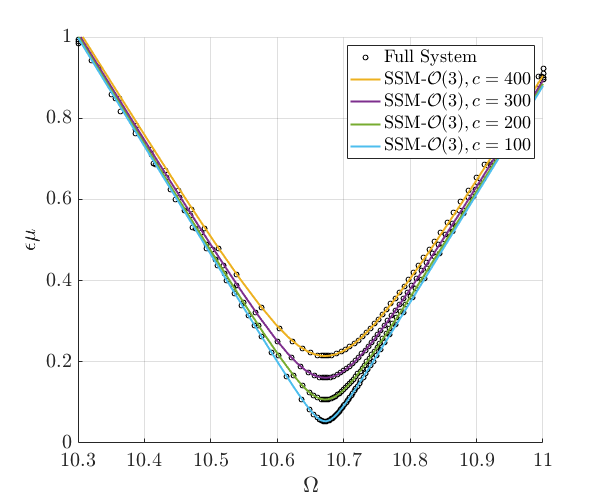

PBplotSD(n,cs); % Plot SD for various damping parameters